clearvars;
addpath("kwave/");

addpath("rir-generator/matlab/");

## RIR vs Kwave

RIR return a room impulse response using the image source method. Because of problems with our own implementation of the IMS we will use this implementation for now. To make sure it is working correctly we will compare it with a simulation of room reverberation using the kwave-toolbox.

### Initial parameters

size = 1024;
spacing = 50e-3/size;
p_source = [0,0];
p_receiver = [150,0];
Nt = 300; % Number of timesteps
dt = 0.001; % (s) Size of timesteps
f = 0.25e6;
omega = 2*pi*f;

### Kwave

As the monopole sound source simulation in kwave doesnt quite work, meaning that even though the results seems plausible, how it is achieved is unclear, especialy how an inital pressure signals magnitude translates into the output pressure observed at every grid point.

Instead we will define a disk around the source center wich will be "fueled" with the pressure signal at that position.

### Kwave grid

We first need to define a computational grid

Nx = size;           % number of grid points in the x (row) direction
Ny = size;           % number of grid points in the y (column) direction
dx = spacing;        % grid point spacing in the x direction [m]
dy = spacing;        % grid point spacing in the y direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy);
medium.sound_speed = 343;  % [m/s]

Define a time grid

%kgrid.Nt = Nt;
%kgrid.dt = dt;
kgrid.makeTime(medium.sound_speed);

### Source disk

We define the source as a disk

disc_radius = 100;    % [grid points]
source.p_mode = 'dirichlet';
source.p_mask = makeCircle(Nx,Ny,p_source(1),p_source(2),disc_radius);


source.p = sin(omega*kgrid.t_array);%.*ones(nr_source_points,length(kgrid.t_array));

### Sensor

We define a single sensor

sensor.mask = zeros(Nx, Ny);
sensor.mask(p_receiver(1)+(Nx/2), p_receiver(2)+(Ny/2)) = 1;
sensor.record = {'p', 'p_final'};

### Simulation

We run the simulation and hope that it works

Running k-Wave simulation...
  start time: 15-Dec-2021 06:49:38
  reference sound speed: 343m/s
  dt: 42.7068ns, t_end: 206.1458us, time steps: 4828
  input grid size: 1024 by 1024 grid points (50 by 50mm)
  maximum supported frequency: 3.5123MHz
  precomputation completed in 0.26876s
  starting time loop...
  estimated simulation time 9min 55.9534s...


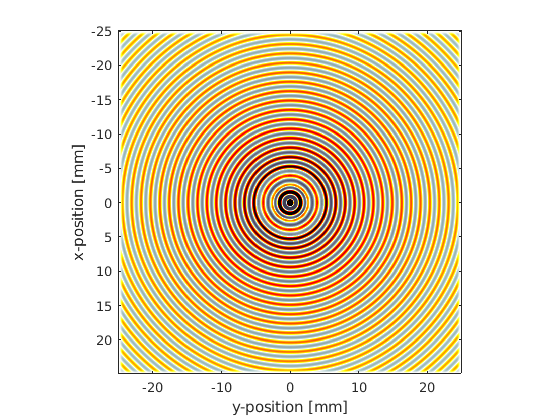

  simulation completed in 11min 51.2621s
  total computation time 11min 51.5992s


sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor);

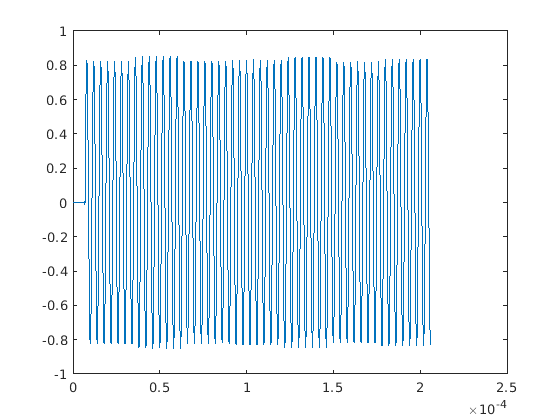

plot(kgrid.t_array, sensor_data.p);